% Example Input (Replace with actual data)
flattened_surface = obj_2D.vt;  % Flattened 2D vertex positions
flattened_surface = [flattened_surface,zeros(size(flattened_surface,1),1)];
deployed_surface = obj_2D.v;    % Deployed 3D vertex positions
faces = obj_2D.f.v

faces_3D =    110     2     1
   111     3     2
   112     4     3
   113     5     4
   114     6   113
   115     7   114
   116     8   115
   117     9     8
   118    10   117
   119    11   118



% Move and rotate the 3D object to match the boundary
% Rotate object 
deployed_surface = [deployed_surface(:,1), deployed_surface(:,3),deployed_surface(:,2)];  

% Move to match the coorespoind node
T = mean(flattened_surface) - mean(deployed_surface);

flattened_surface = flattened_surface - [T(:,[1,2]),0];


## Plot the 3D configuration and 2D configuration

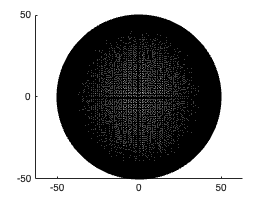

% Plot the results
% Plot the 3D configurations
figure()
patch('Vertices', deployed_surface, 'Faces', faces, ...
      'FaceColor','none', 'EdgeColor', 'black');
axis equal;          % Equal scaling for all axes

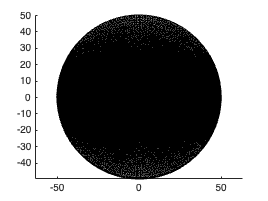

%axis off;
%view(3);             % Set default 3D view angle

figure()
axis equal;
patch('Vertices', flattened_surface, 'Faces', faces, ...
    'FaceColor', 'none', 'EdgeColor', 'black'); % Plot 2D figure

%view(3);             % Set default 3D view angle



## Deploy the 2D configuration

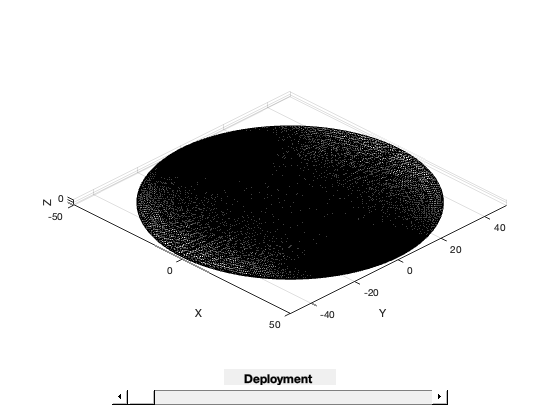

% Initialize figure
fig = figure('Color', 'w');
hold on;
xlabel('X'); ylabel('Y'); zlabel('Z');
view(45, 30);
grid on; axis equal;

% Create a patch object for deployment
hPatch = patch('Vertices', flattened_surface, 'Faces', faces_2D, ...
               'FaceColor', 'none', 'EdgeColor', 'black', 'FaceAlpha', 0.6);

% Create UI slider
slider = uicontrol('Style', 'slider', 'Min', 0, 'Max', 1, 'Value', 0, ...
                   'Units', 'normalized', 'Position', [0.2 0.02 0.6 0.05], ...
                   'Callback', @updateDeployment);

% Create label
uicontrol('Style', 'text', 'String', 'Deployment Control', ...
          'Units', 'normalized', 'Position', [0.4 0.08 0.2 0.04], ...
          'FontSize', 12, 'FontWeight', 'bold');

function updateDeployment(src, ~)
    alpha = src.Value; % Get slider value
    V_deploy = (1 - alpha) * flattened_surface + alpha * deployed_surface;
    hPatch.Vertices = V_deploy; % Update patch vertices
    title(['Deployment Step: ' num2str(round(alpha*100)) ' %']);
    drawnow;
end
